clear all;

v=0;
s=0;

v1= 20/3.6;
v2= 30/3.6;
Cd= 0.14;
Cr= 0.0025;
A= 1.7577;
rho= 1.15;

m= 210;
g= 9.81;
F= 500;
t= 1;

Froll= Cr*m*g;

v_list=[];
s_list=[];
a_list=[];
iter=0;

while(s<940)
    if v>=0 && v<=v1
        Fdrag= 0.5* rho* A* Cd*v^2;
        a= (F- (Fdrag+Froll))/m;
        
    elseif v>v1 && v<= v2
        Fdrag= 0.5* rho* A* Cd*v^2;
        a= (F/2- (Fdrag+Froll))/m;
        
    elseif v>v2
        Fdrag= 0.5* rho* A* Cd*v^2;
        a= - (Fdrag+Froll)/m;
        
    end
    
    v=v+a*t;
    s= s+ v*t;
    
    v_list= [v_list; v];
    s_list= [s_list; s];
    a_list= [a_list; a];
    iter= iter+1;
end

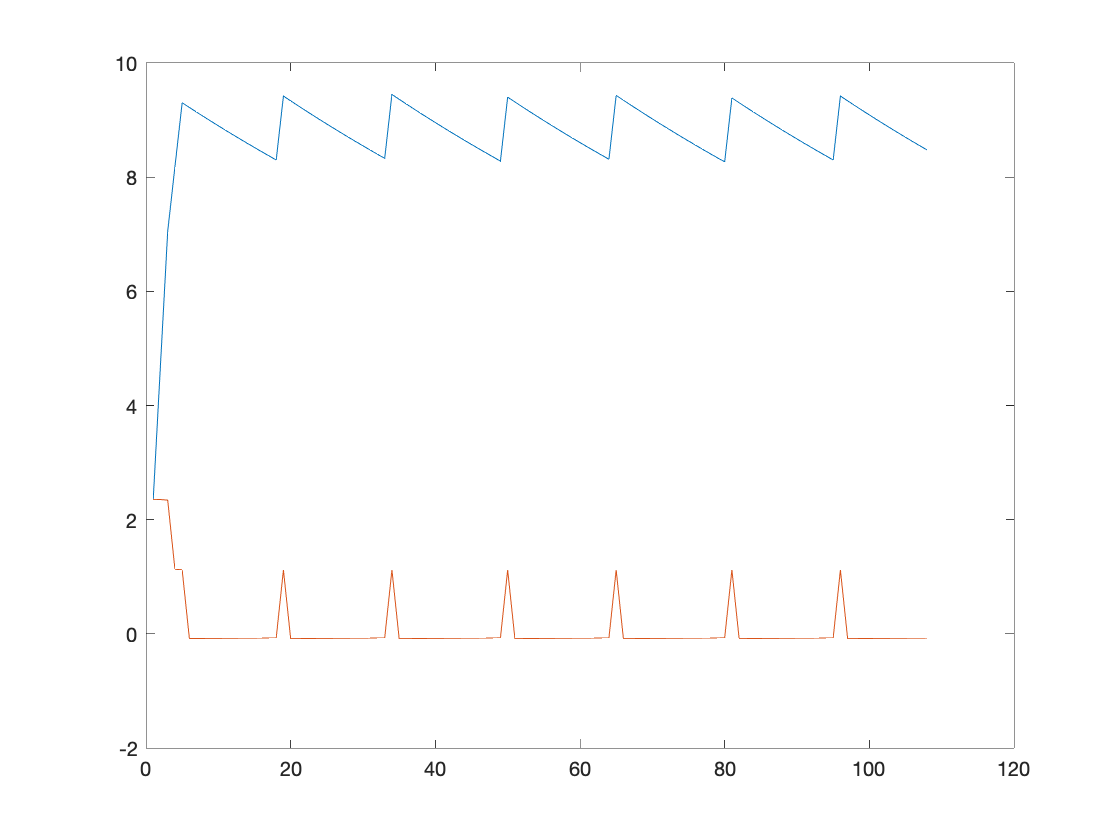

close all;
plot(v_list);
hold on;
plot(a_list);
hold off;

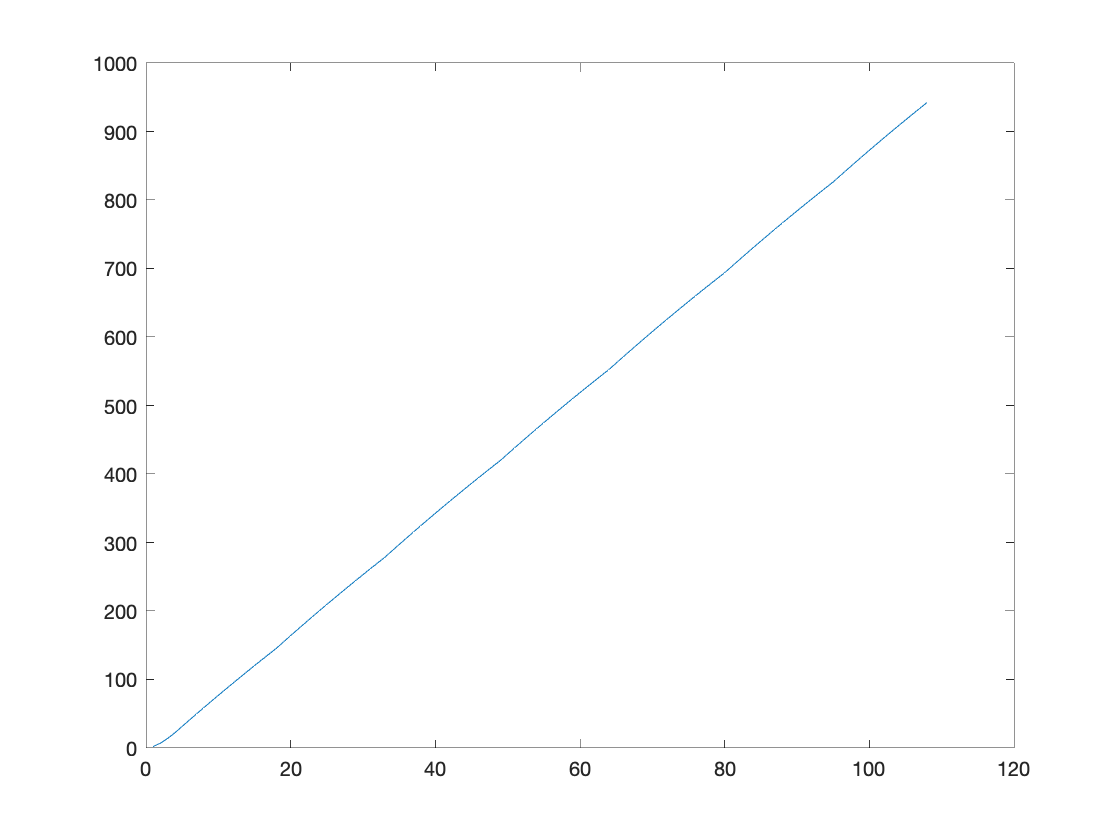


figure;
plot(s_list)